# Load file

y -- Actual data sequence Fs -- Stated frequency of sampling NN -- number of data points

Fs = 7000; Channels = 1; bits = 24;
r = audiorecorder(Fs, bits, Channels);
duration = 3.5; disp('Started');
recordblocking(r, duration);
disp("Stopped");
X = getaudiodata(r);

sound(X, Fs, bits);

filename = 'highpitch.wav';
audiowrite(filename, X, Fs);

[y,Fs] = audioread('highpitch.wav');
sound(y,Fs)
NN=length(y);

## Plot data

For reference and visualization tt -- time variable= data index * Fs;

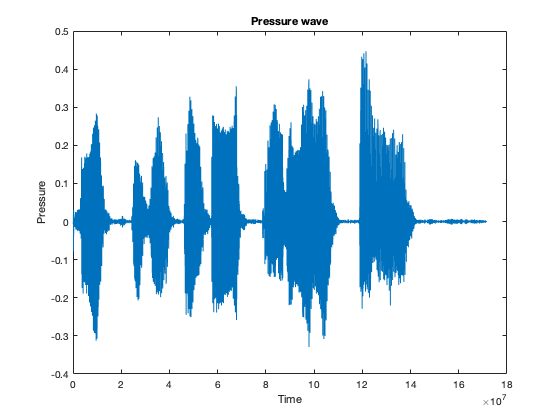

tt=(0:(NN-1))*Fs;
soundData=figure('Name', 'Sound data');
plot(tt, y);
xlabel('Time'); ylabel('Pressure');
title('Pressure wave');

## Fourier Transform

The fft gives a sequence 0:(N-1). Uses function fft- discrete Fourier transform Uses function fftshift - The FT is periodic. This shifts the FT from 0-N-1 to -(N-1)/2:(N-1)/2 if N odd or to -N/2:(N-1)/2 if N even. fS space of frequencies. The highest frequency is Fs and corresponds to the index N in spectral space. fS runs from 0 to Fs(NN-1)/N; fSH space of shifted frequencies corresponding to fftshift.

myFFT --Fourier transform of sample. myFFTH --Shifted Fourier transform of sample. myFFTR --Real part of Fourier transform of sample. myFFTI --Imaginary part of Fourier transform of sample.

myFFT=fft(y);
myFFTR=real(myFFT); %Real Components
myFFTI=imag(myFFT); %Imaginary Components

myFFTH=fftshift(myFFT);
myFFTHR=real(myFFTH);
myFFTHI=imag(myFFTH);

fS=(0:(NN-1))*Fs/NN;

if  rem(NN,2)==1  % Is NN odd?
    fSH=(-(NN-1)/2):((NN-1)/2);
    fSH=fSH*Fs/NN; %sets the scale
else
    fSH=((-NN/2):((NN-1)/2));
    fSH=fSH*Fs/NN; %sets the scale
end

## Plots of transform no shift

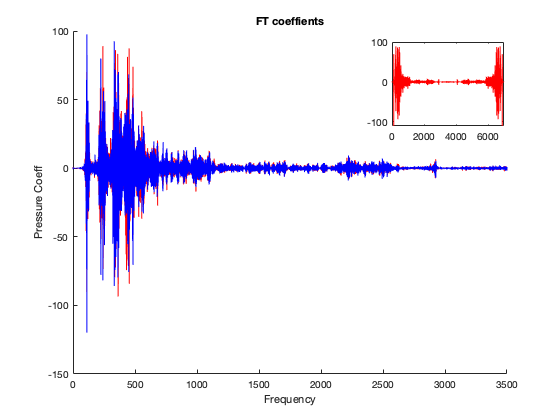

fTPL1=figure('Name','Re and Im of Tranform');
hold on;
plot(fS, myFFTR, 'r');
plot(fS, myFFTI, 'b');
xlabel('Frequency');
ylabel('Pressure Coeff');
title('FT coeffients');
xlim([0 3500]); % Only show up to 1000 Hz

axPL12 = axes('Position',[.7 .7 .2 .2]);  % for inset
box on;
plot(fS,myFFTR,'r');

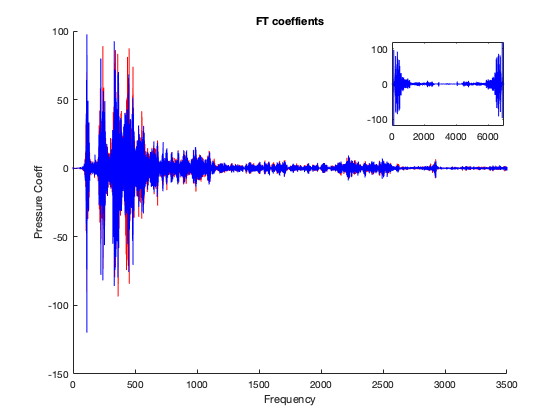

plot(fS,myFFTI,'b');

## Plots of transform with shift

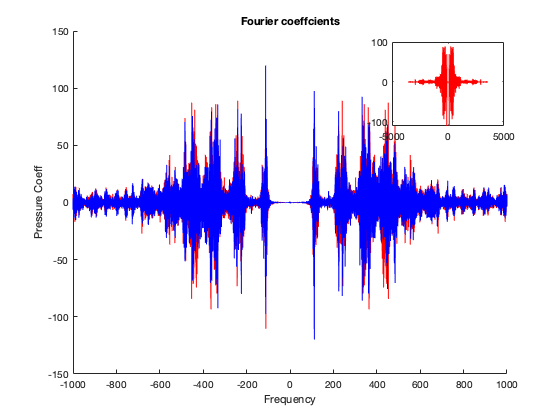

fTPL2=figure('Name','Re and Im of Tranform');
hold on;
plot(fSH, myFFTHR, 'r');
plot(fSH, myFFTHI, 'b');
xlabel('Frequency');
ylabel('Pressure Coeff');
title('Fourier coeffcients');
xlim([-1000 1000]); % Only show center
axPL22 = axes('Position',[.7 .7 .2 .2]);  % for inset
box on;
plot(fSH,myFFTHR,'r');

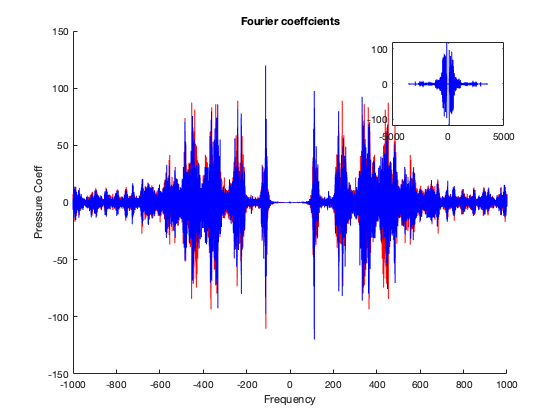

plot(fSH,myFFTHI,'b');

## Filters

## Flter A

High pass. Kill all the componets at high frequency To recreate the pressure wave we do inverse tranform. yA pressure wave cA Cutoff in Hertz

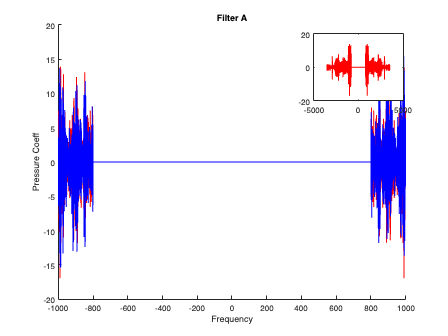

cA=800;
indA=(abs(fSH)>cA);
myFFTAH=zeros(NN,1); % Set zero everyhwere
myFFTAH(indA)=myFFTH(indA); % Copy only in the region selected
myFFTAHR=real(myFFTAH);
myFFTAHI=imag(myFFTAH);
myFFTA=ifftshift(myFFTAH); % inverseShift
myFFTAR=real(myFFTA);
myFFTAI=real(myFFTA);

fTPL3=figure('Name','Re and Im of filter A');
hold on;
plot(fSH, myFFTAHR, 'r');
plot(fSH, myFFTAHI, 'b');
xlabel('Frequency');
ylabel('Pressure Coeff');
title('Filter A');
xlim([-1000 1000]); % Only show center
axPL23 = axes('Position',[.7 .7 .2 .2]);  % for inset
box on;
plot(fSH,myFFTAHR,'r');

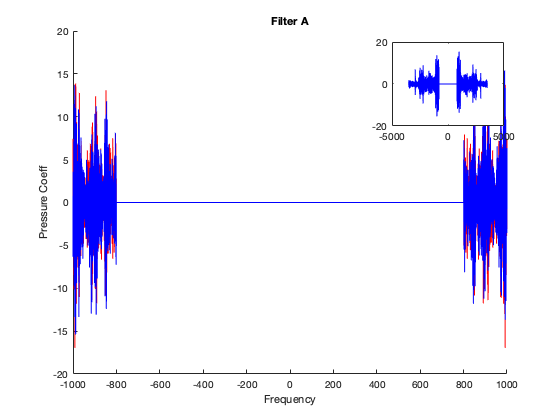

plot(fSH,myFFTAHI,'b');

yA=real(ifft(myFFTA));

audiowrite('soundFilteredA.wav',yA,Fs);
[y,Fs] = audioread('highpitch.wav');
sound(y,Fs)
pause(4);
[y,Fs] = audioread('soundFilteredA.wav');
sound(y,Fs)

## Flter B

Low pass. Kill all the componets at low frequency To recreate the pressure wave we do inverse tranform. yB pressure wave

## cB Cutoff in Hertz

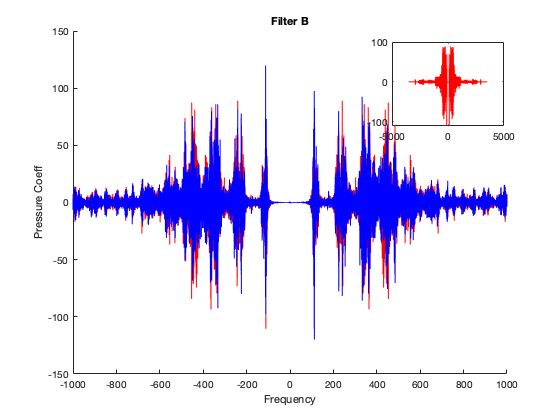

cB=1600;
indB=(abs(fSH)<cB);
myFFTBH=zeros(NN,1); % Set zero everyhwere
myFFTBH(indB)=myFFTH(indB); % Copy only in the region selected
myFFTBHR=real(myFFTBH);
myFFTBHI=imag(myFFTBH);
myFFTB=ifftshift(myFFTBH); % inverseShift
myFFTBR=real(myFFTB);
myFFTBI=real(myFFTB);

fTPL3=figure('Name','Re and Im of filter B');
hold on;
plot(fSH, myFFTBHR, 'r');
plot(fSH, myFFTBHI, 'b');
xlabel('Frequency');
ylabel('Pressure Coeff');
title('Filter B');
xlim([-1000 1000]); % Only show center
axPL23 = axes('Position',[.7 .7 .2 .2]);  % for inset
box on;
plot(fSH,myFFTBHR,'r');

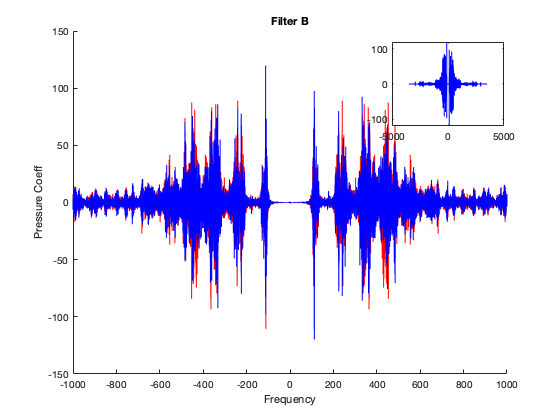

plot(fSH,myFFTBHI,'b');

yB=real(ifft(myFFTB));
yB = yB * 1.2 + 0.8

yB =     0.7998
    0.7999
    0.8005
    0.7992
    0.8009
    0.7991
    0.8007
    0.7996
    0.8000
    0.8004


audiowrite('soundFilteredB.wav',yB,Fs);

[y,Fs] = audioread('highpitch.wav');
sound(y,Fs)
pause(4);
[y,Fs] = audioread('soundFilteredB.wav');
sound(y,Fs)

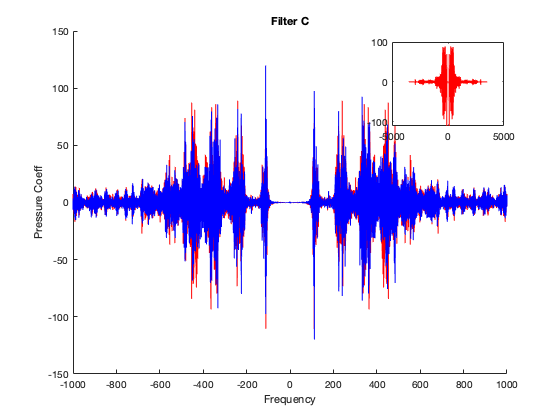

cC = 1600;
cC2 = 3100;

indC = (abs(fSH) > cC2) | (abs(fSH) < cC);

myFFTCH=zeros(NN,1); % Set zero everyhwere
myFFTCH(indC)=myFFTH(indC); % Copy only in the region selected
myFFTCHR=real(myFFTCH);
myFFTCHI=imag(myFFTCH);
myFFTC=ifftshift(myFFTCH); % inverseShift
myFFTCR=real(myFFTC);
myFFTCI=real(myFFTC);

fTPL3=figure('Name','Re and Im of filter C');
hold on;
plot(fSH, myFFTCHR, 'r');
plot(fSH, myFFTCHI, 'b');
xlabel('Frequency');
ylabel('Pressure Coeff');
title('Filter C');
xlim([-1000 1000]); % Only show center
axPL23 = axes('Position',[.7 .7 .2 .2]);  % for inset
box on;
plot(fSH,myFFTBHR,'r');

yC=real(ifft(myFFTC));
yC = yC + 0.4;

audiowrite('soundFilteredC.wav',yC,Fs);
[y,Fs] = audioread('highpitch.wav');
sound(y,Fs)
pause(4);
[y,Fs] = audioread('soundFilteredC.wav');
sound(y,Fs)